clear
load clown
clown(20,319)

ans = 0.1554

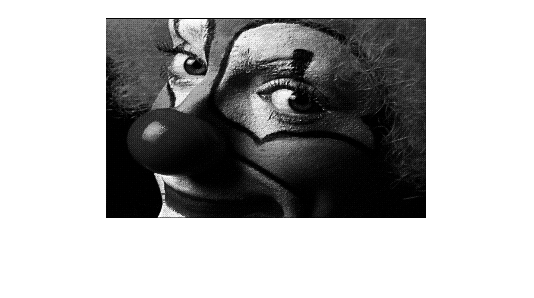

imshow(clown)


test = Rotate(clown, 180)

test =          0         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0085         0    0.0241         0    0.0085         0    0.0085         0    0.0241         0    0.0241         0    0.0241         0    0.0241         0    0.0085         0    0.0085         0    0.0241         0    0.0241         0    0.0085         0
         0         0         0         0         0         0         0         0         0    0.0085         0         0         0    0.0085         0         0         0         0         0         0         0    0.0085         0         0         0         0         0    0.0085         0         0         0         0         0         0         0    0.0241         0         0         0         0         0         0         0    0.0085         0         0         0    0.0085         0  

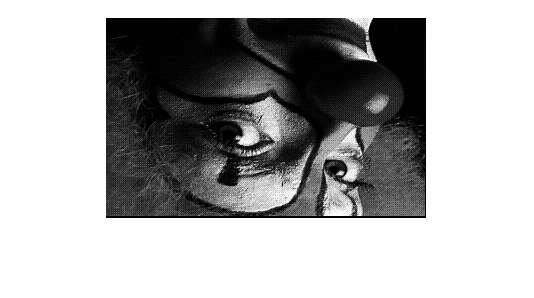

imshow(test, [])

function [Out] = Rotate(In, Theta)

% Converting Theta to radians
Theta = deg2rad(Theta);

% Calculating number of rows and colums in the input image
[rows, cols] = size(In);

% Forward rotation matrix
tm = [cos(Theta), -sin(Theta);
    sin(Theta), cos(Theta)];

% Performing the inverse of the transformation matrix for reverse mapping
itm = inv(tm);

% Initialise output
Out = zeros(rows, cols, class(In));

% Locating the centre point of the input image 
cp = [((rows)/2); ((cols)/2)];

for r = 1:rows          % Desitnation row
    for c = 1:cols      % Destination col
        p = [r; c];     % Destination point
        
        % Reverse mapping equation
        tp = itm * (p - cp) + cp;   % Source

        % Nearest Neighbour
        rs = round(tp(1));      % rs = row of source
        cs = round(tp(2));      % cs = colums of source


        % Bound Check
        if rs < 1 || rs > rows || cs < 1 || cs > cols
            Out(r,c) = 0;       % Paint Black
        else
            Out(r,c) = In(rs,cs);   % Paint from source
        end
    end
end
end